%牛顿迭代法求sqrt(2)
a=2;
if a<0
    warning("a must >0");
end
x = a/2; 
while true
     x1 = (x+a/x)/2;
     %前后两次结果之差处于精度范围内则输出
     if abs(x-x1)<1e-5
        break;
     end
     %最后输出的是x1的值
     x = x1;  
end
disp(x);

    1.4142



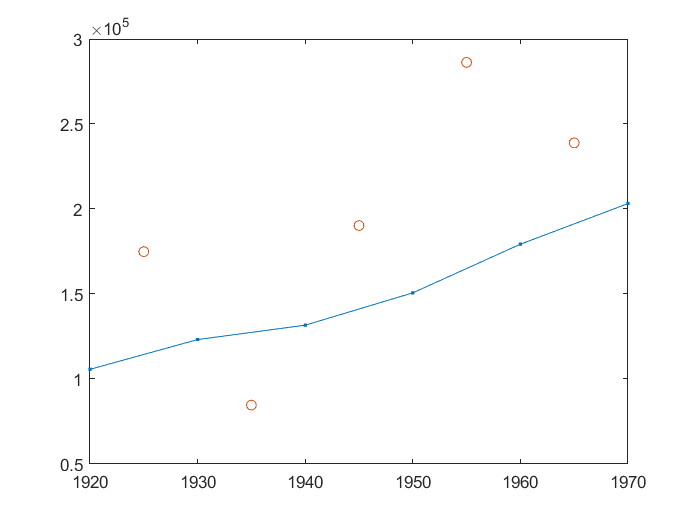

clear;

year_10=1920:10:1970;
num_10=[105711,123203,131669,150697,179323,203212];

%十年人口增长率
k=@(i)(num_10(i+1)-num_10(i))/(year_10(i+1)-year_10(i));

plot(year_10,num_10,'.-');
hold on;

kn=[];
for i=1:5
    kn=[kn,k(i)];
end

year_5=1925:10:1965;
plot(year_5,kn*100,'o');

hold off

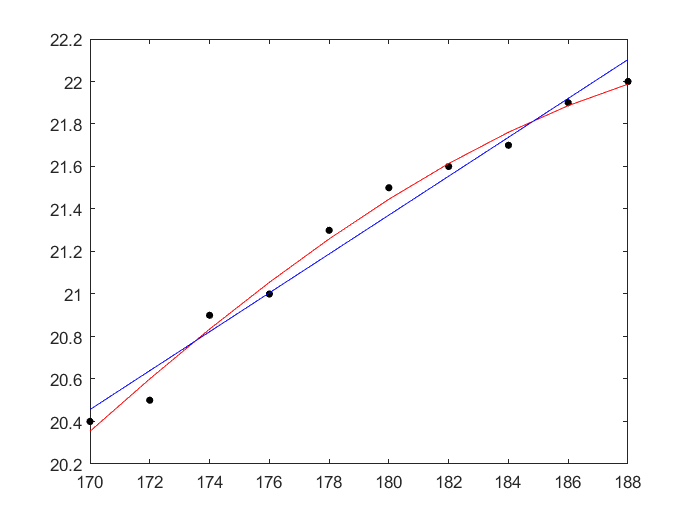

%身高与脚长的关系
clear;
high=170:2:188;
long=[20.4,20.5,20.9,21.0,21.3,21.5,21.6,21.7,21.9,22.0];
plot(high,long,'k.','markersize',15);
hold on

%多项式曲线拟合
P3=polyfit(high,long,3);  
t=170:2:188;
S3=polyval(P3,t);  
plot(t,S3,'r');

%直线拟合
X=high;
Y=long;
x = mean(X); % X的均值
y = mean(Y); % Y的均值
b_0 = (X-x) * ((Y-y).') / ((X-x) * ((X-x).')); % 斜率
b_1 = y - b_0 .* x; % 截距
y_pred = b_0 .* X + b_1; % 预测的y值
plot(X, y_pred,'b');
hold off